# Search a Slide for Content

Find a content object in an `mlreportgen.ppt.Slide` object by using the `find` method.

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation.

ppt = Presentation('mySlideFindPresentation.pptx');
open(ppt);

Add a slide with a `Title and Content` layout.

slide = add(ppt,'Title and Content');

Search the slide for a content object that has the `Name` property value `'Content'`.

contents = find(slide,'Content')

`find` returns a 1-by-1 array that contains an `mlreportgen.ppt.ContentPlaceholder` object. Specify that the text in the placeholder object is bold and add text to the object.

contents(1).Bold = true;
add(contents(1),'This is bold text');

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the generated presentation:

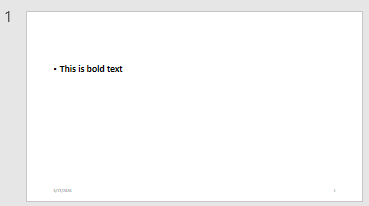

*Copyright 2020 The MathWorks, Inc.*